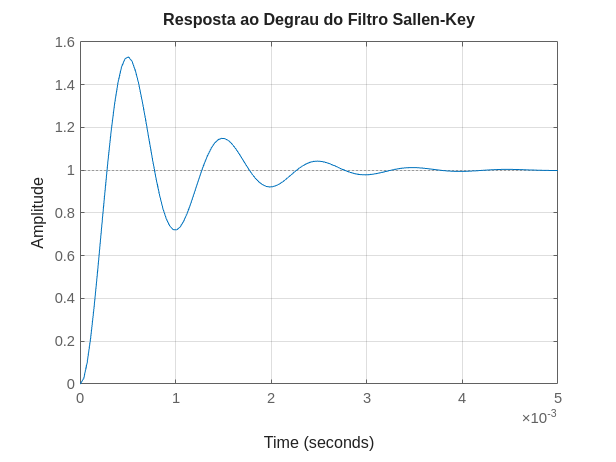



% Carregar saída do subtrator
load('V_subtrator.mat', 'V_subtrator', 't', 'Fs');

% faotr de amortecimento 0.2 e fc = 1000
% Parâmetros do filtro
R1 = 13e3; R2 = 5.6e3; 
C1 = 0.1e-6; C2 = 0.0033e-6;

% Função de transferência
s = tf('s');
G_filtro = (1/(R1*C1*R2*C2)) / (s^2 + s*(1/(R2*C1) + 1/(R1*C1)) + 1/(R1*C1*R2*C2));

% Resposta ao degrau
figure;
step(G_filtro);
title('Resposta ao Degrau do Filtro Sallen-Key');
%ylim([0 2]);       
grid on;

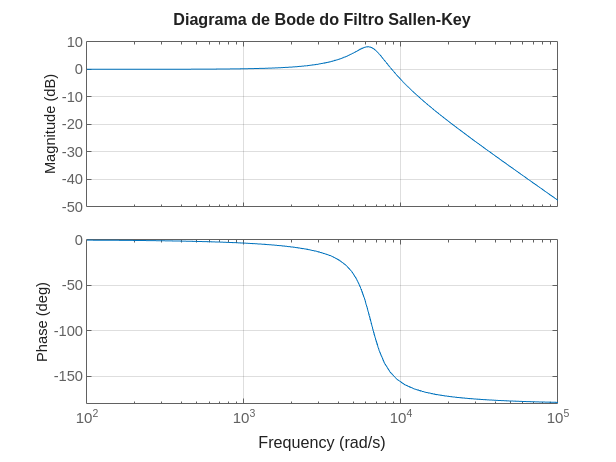


% Diagrama de Bode
figure;
bode(G_filtro);
title('Diagrama de Bode do Filtro Sallen-Key');
grid on;


% Simulação
V_subtrator = V_subtrator(:); % Converter para vetor coluna
V_filtrado = lsim(G_filtro, V_subtrator, t);

% Salvar saída
save('V_filtrado.mat', 'V_filtrado', 't', 'Fs');
disp('Saída do filtro salva em dados/V_filtrado.mat');

Saída do filtro salva em dados/V_filtrado.mat


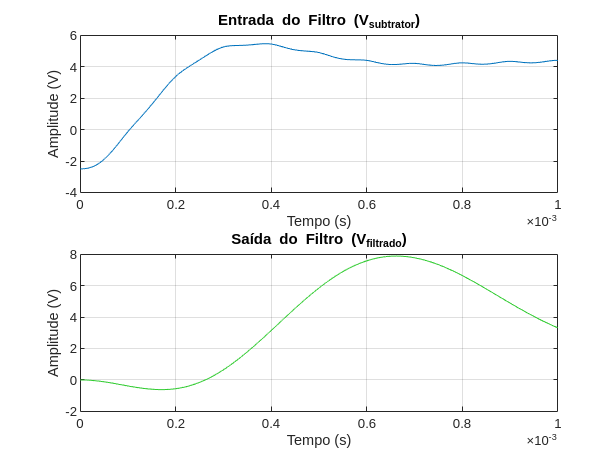


% Plotagem
figure;
subplot(2,1,1);
plot(t, V_subtrator);
title('Entrada do Filtro (V_{subtrator})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;

subplot(2,1,2);
plot(t, V_filtrado,  'Color', [0.2 0.8 0.2]);
title('Saída do Filtro (V_{filtrado})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;